## Modeling World Population Growth

### Introduction

In 1968 Paul Erlich published *The Population Bomb*, in which he predicted that world population would grow quickly during the 1970s, that agricultural production could not keep up, and that mass starvation in the next two decades was inevitable (see [https://en.wikipedia.org/wiki/The_Population_Bomb](https://en.wikipedia.org/wiki/The_Population_Bomb)).  As someone who grew up during those decades, I am happy to report that those predictions were wrong.

But world population growth is still a topic of concern, and it is an open question how many people the earth can sustain while maintaining and improving our quality of life.

In this case study, we use simple models to explain world population growth since 1950 and generate predictions for the next 50--100 years.

For background on world population growth, watch this video from the American Museum of Natural History: [https://www.youtube.com/watch?v=PUwmA3Q0_OE.](https://www.youtube.com/watch?v=PUwmA3Q0_OE.)

### Data

The Wikipedia article on world population estimates ([https://en.wikipedia.org/wiki/World_population_estimates](https://en.wikipedia.org/wiki/World_population_estimates)) summarizes data from the United Nation and U.S. Census Bureau, which I have converted to CSV files.

Here's the data from the UN Department of Economic and Social Affairs (DESA):

filename = '../data/world_pop_un.csv';
m = readmatrix(filename);
year = m(:,1);
un = m(:,2)'

un =     2.5251    2.5729    2.6193    2.6659    2.7132    2.7617    2.8116    2.8630    2.9160    2.9704    3.0260    3.0828    3.1411    3.2012    3.2637    3.3291    3.3975    3.4685    3.5417    3.6161    3.6912    3.7668    3.8429    3.9192    3.9953    4.0710    4.1461    4.2208    4.2957    4.3715    4.4490    4.5282    4.6090    4.6916    4.7764    4.8636    4.9534    5.0453    5.1382    5.2300    5.3208    5.4089    5.4949    5.5789    5.6611    5.7418    5.8210    5.8987    5.9753    6.0515


And from the U.S. Census Bureau:

filename = '../data/world_pop_census.csv';
m = readmatrix(filename);
census = m(:,2)'

census =     2.5576    2.5949    2.6368    2.6821    2.7302    2.7821    2.8353    2.8913    2.9481    3.0007    3.0430    3.0840    3.1401    3.2098    3.2812    3.3504    3.4207    3.4903    3.5623    3.6372    3.7127    3.7903    3.8666    3.9421    4.0166    4.0891    4.1602    4.2321    4.3041    4.3790    4.4514    4.5344    4.6146    4.6957    4.7746    4.8565    4.9406    5.0272    5.1146    5.2014    5.2890    5.3716    5.4561    5.5383    5.6187    5.6992    5.7794    5.8580    5.9352    6.0121


Here's what their estimates look like from 1950 to 2016.

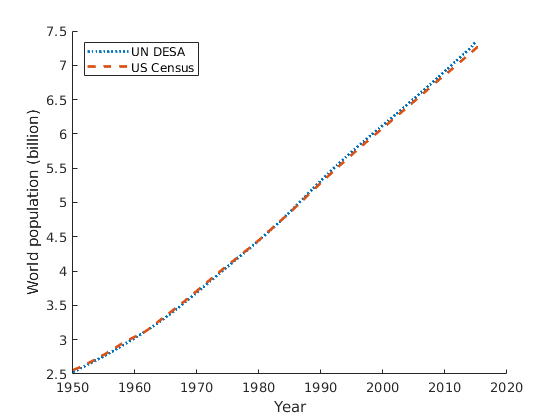

clf; hold on

plot(year, un, ':', 'LineWidth', 2)
plot(year, census, '--', 'LineWidth', 2)
legend('UN DESA', 'US Census', 'Location', 'northwest')

xlabel('Year')
ylabel('World population (billion)')

To get a sense of how accurate these estimates are, we can see how different they are.

The following expression computes the elementwise differences between the two series, then divides through by the UN value to produce relative errors (see [https://en.wikipedia.org/wiki/Approximation_error](https://en.wikipedia.org/wiki/Approximation_error)), then finds the largest element.

The largest relative error between the estimates is about 1.3%.

rel_error = abs(census - un) ./ un

rel_error =     0.0129    0.0086    0.0067    0.0061    0.0063    0.0074    0.0084    0.0099    0.0110    0.0102    0.0056    0.0004    0.0003    0.0027    0.0054    0.0064    0.0068    0.0063    0.0058    0.0058    0.0058    0.0063    0.0062    0.0058    0.0053    0.0044    0.0034    0.0027    0.0020    0.0017    0.0005    0.0014    0.0012    0.0009    0.0004    0.0015    0.0026    0.0036    0.0046    0.0055    0.0060    0.0069    0.0071    0.0073    0.0075    0.0074    0.0071    0.0069    0.0067    0.0065


percent_error = rel_error * 100

percent_error =     1.2862    0.8585    0.6674    0.6072    0.6286    0.7404    0.8439    0.9887    1.1011    1.0208    0.5617    0.0369    0.0311    0.2702    0.5350    0.6399    0.6829    0.6289    0.5827    0.5821    0.5832    0.6258    0.6166    0.5847    0.5332    0.4437    0.3388    0.2670    0.1965    0.1712    0.0520    0.1364    0.1216    0.0890    0.0382    0.1468    0.2585    0.3591    0.4604    0.5461    0.5988    0.6900    0.7054    0.7277    0.7490    0.7423    0.7142    0.6903    0.6709    0.6511


max_percent_error = max(percent_error)

max_percent_error = 1.3821

### Constant growth model

Suppose we want to predict world population growth over the next 50 or 100 years.  We can do that by developing a model that describes how populations grow, fitting the model to the data we have so far, and then using the model to generate predictions.

I will demonstrate this process starting with simple models and gradually improving them.

Although there is some curvature in the plotted estimates, it looks like world population growth has been close to linear since 1960 or so.  So we'll start with a model that has constant growth.

To fit the model to the data, I'll compute the average annual growth from 1950 to 2016.  Since the UN and Census data are so close, I'll use the Census data.

Here are the first and last elements of the series (in billions):

p_0 = census(1)

p_0 = 2.5576

p_end = census(end)

p_end = 7.3260

And here is the elapsed time in years:

t_0 = year(1)

t_0 = 1950

t_end = year(end)

t_end = 2016

elapsed_time = t_end - t_0

elapsed_time = 66

 Then we can compute the average annual growth in billions of people per year.

total_growth = p_end - p_0

total_growth = 4.7684

annual_growth = total_growth / elapsed_time

annual_growth = 0.0722

Our simulation will start with the observed population in 1950, `p_0`, and add `annual_growth` each year.  To store the results, I'll create a vector the same size as `census`.

results = zeros(size(census));

 Initially `results` is all zeros.  I'll initialize it so the starting value, in 1950, is the 1950 population estimated by the US Census.

results(1) = census(1)

results =     2.5576         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


Now I'll run a loop from 1 to the length of `census`, filling in the elements of `results`.

for i = 1:length(census)-1
    results(i+1) = results(i) + annual_growth;
end

Here's what the results looks like, compared to the actual data.

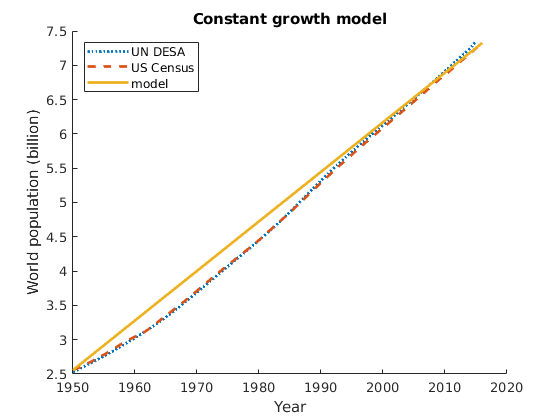

clf; hold on

plot(year, un, ':', 'LineWidth', 2)
plot(year, census, '--', 'LineWidth', 2)
plot(year, results, 'LineWidth', 2)
legend('UN DESA', 'US Census', 'model', 'Location', 'northwest')

xlabel('Year') 
ylabel('World population (billion)')
title('Constant growth model')

The model does not fit the data particularly well from 1950 to 1990, but after that, it's pretty good.  Nevertheless, there are problems:

- There is no obvious mechanism that could cause population growth to be constant from year to year.  Changes in population are determined by the fraction of people who die and the fraction of people who give birth, so we expect them to depend on the current population.

- According to this model, we would expect the population to keep growing at the same rate forever, and that does not seem reasonable.

We'll try out some different models in the next notebook.